#### Resampling na 100 Gs/s

Korzystaj z plików z kopii zapasowej.

x100 = resample(x,100,10);

#### Korelacja

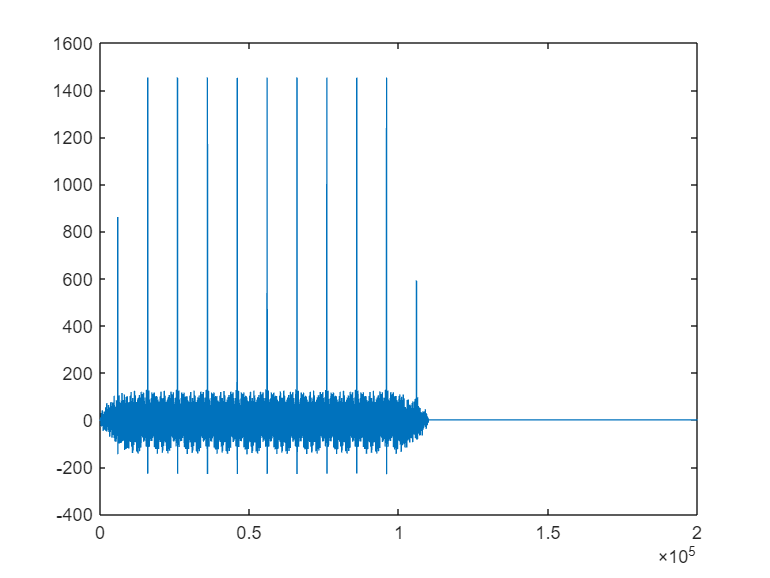

plot(xcorr(x100,gen100));

#### Przycięcie

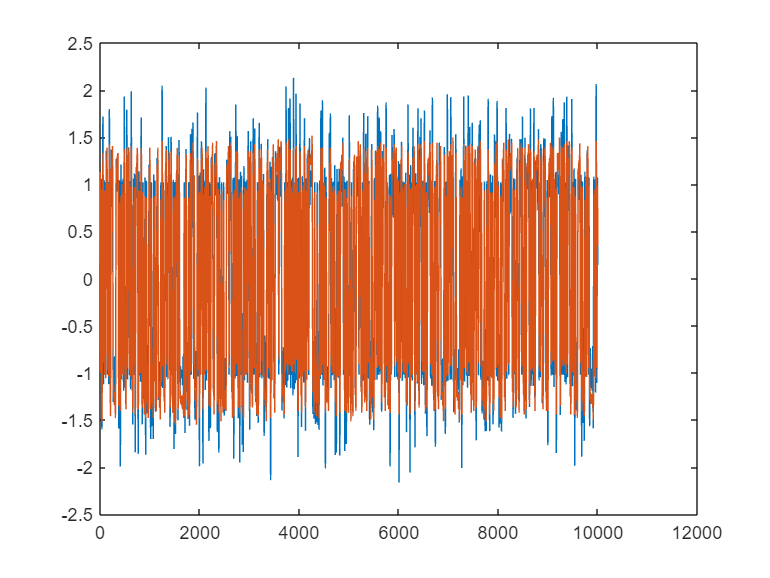

fd = finddelay(x100,gen100);
gen_cut = gen100(fd:fd+10000);

x100=x100./rms(x100);
gen_cut=gen_cut./rms(gen_cut);

figure(1)
plot(x100)
hold on
plot(gen_cut)
hold off

#### Zmiana fazy

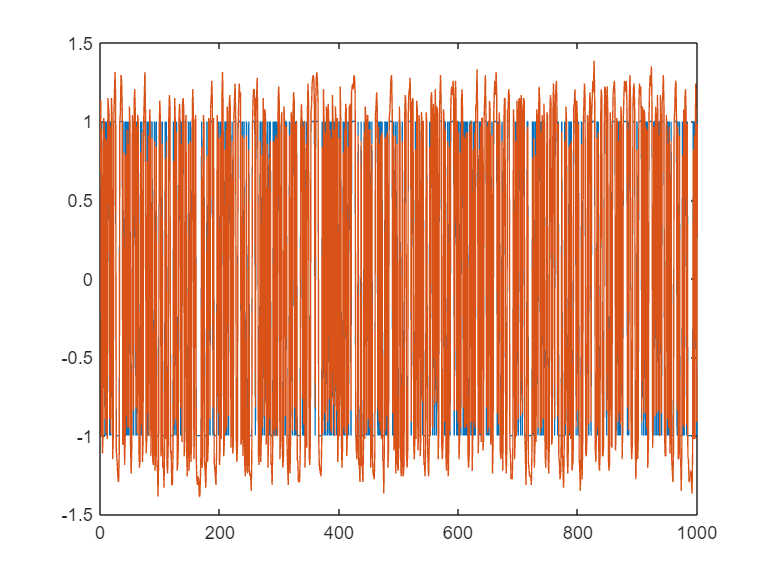

gen_cut_ds = downsample(gen_cut(3:end),10);

figure(2)
plot(x)
hold on
plot(gen_cut_ds)
hold off

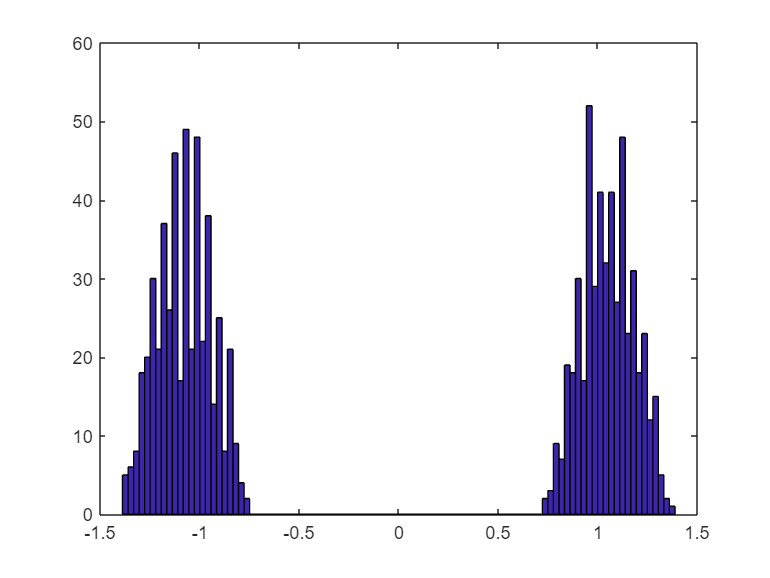

hist(gen_cut_ds,100)

#### Zamiana na 0 i 1

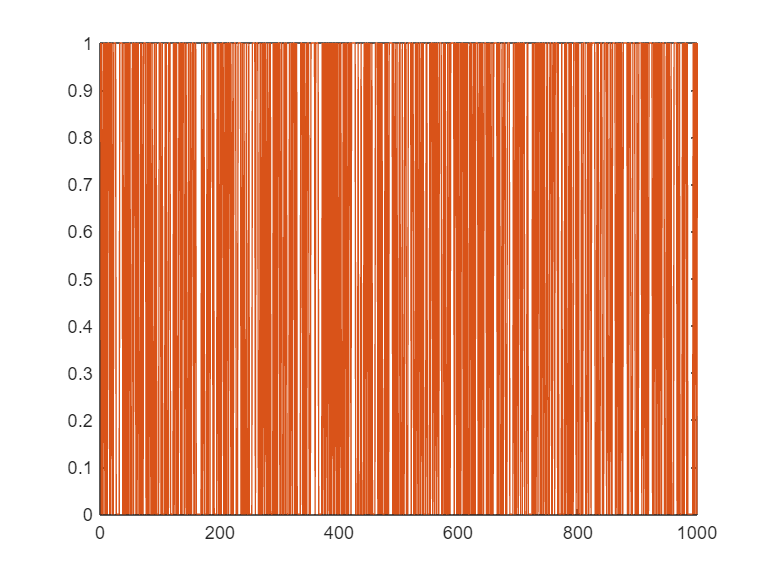

gen_cut_ds_dig = ones(1000,1);

for i=1:length(gen_cut_ds_dig)
    if gen_cut_ds(i,1) < -0.5
        gen_cut_ds_dig(i,1)=0;
    end
    if gen_cut_ds(i,1) > 0.5
        gen_cut_ds_dig(i,1)=1;
    end
end

x_norm = x+1;
x_norm = x_norm/2;

figure(4)
plot(x_norm)
hold on
plot(gen_cut_ds_dig)
hold off

#### Sprawdzenie

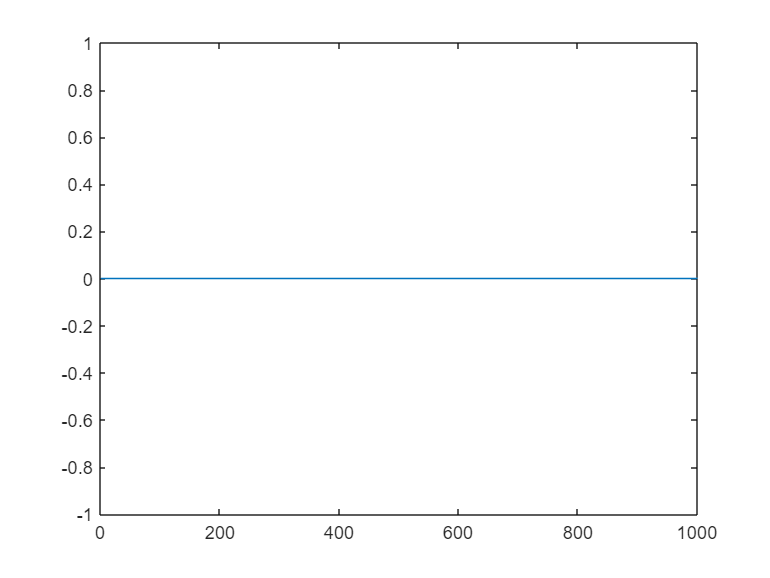

for i=1:1000
    diff(i,1)=x_norm(i,1)-gen_cut_ds_dig(i,1);
end
plot(diff)